# Intersecting datasets

## LeRoy and CCLE Chromatin Profiles

leroy = readtable('~/Data/Expression/Proteomics/MatchingGCPs.xlsx', ...
    "Sheet", 'LeRoy', ...
    "ReadVariableNames", true, ...
    "ReadRowNames", true);

gcp = readtable('~/Data/Expression/Proteomics/MatchingGCPs.xlsx', ...
    "Sheet", 'GCP', ...
    "ReadVariableNames", true, ...
    "ReadRowNames", true);

[~, ia, ib] = intersect(leroy.Properties.RowNames, gcp.Properties.RowNames);
leroy_markers = leroy.Properties.VariableNames;
gcp_markers = gcp.Properties.VariableNames;

leroy = table2array(leroy); leroy = leroy(ia, :);
gcp = table2array(gcp); gcp = gcp(ib, :);

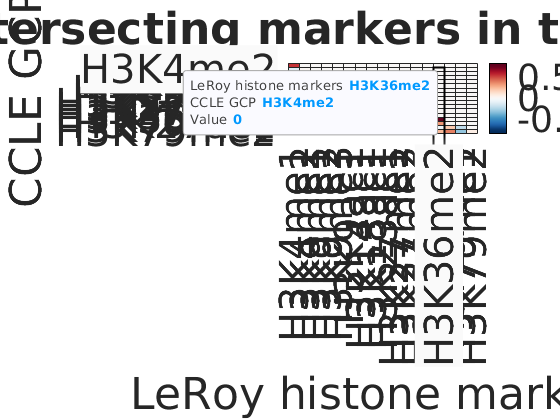

[corrmat, pmat] = corr(leroy, gcp);
corrmat(pmat > 0.05) = NaN;
redbluecmap = imresize(redbluecmap, [1000, 3]); 
redbluecmap = min(max(redbluecmap, 0), 1);
heatmap(tril(corrmat), ...
        'colormap', redbluecmap, ...
        'YData', gcp_markers, ...
        'XData', leroy_markers, ...
        'FontSize', 30)
xlabel('LeRoy histone markers');
ylabel('CCLE GCP');
title('Relationship between intersecting markers in the LeRoy and CCLE GCP datasets');